# CLUSTERVAR

Use hierarchical clustering to cluster the basketball statistics variables.

## Load data

load bbstats

## Find linkage between variables

Transpose the `statsnorm `vector to find linkage between the basketball statistics variables. 

varnorm = statsnorm';
Z = linkage(varnorm,'ward');

## Create dendrogram

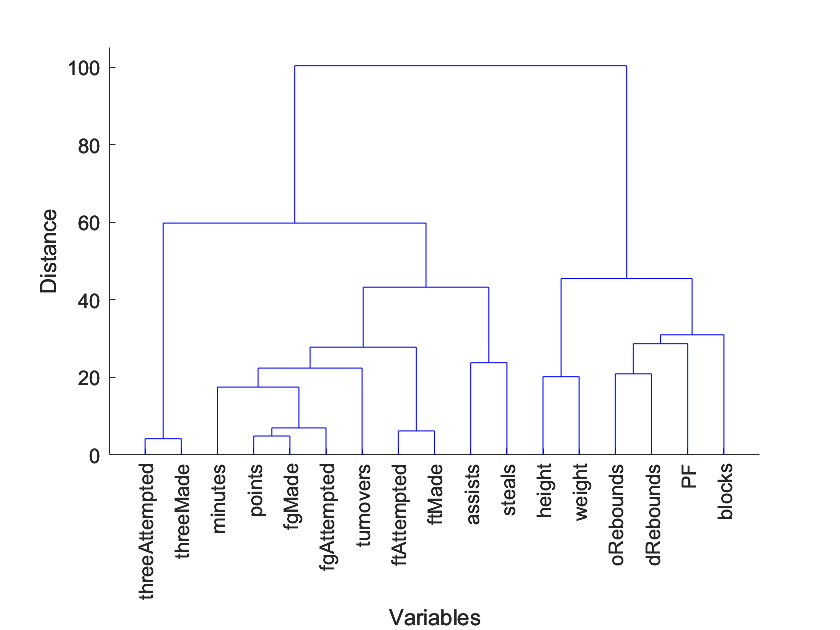

a=axes;
[~,~,outperm] = dendrogram(Z);
xlabel('Variables')
ylabel('Distance')
ticklabels = labels(outperm);
a.XTickLabel = ticklabels;
a.XTickLabelRotation = 90;

## Cluster the linkage into 4 clusters

grp = cluster(Z,'maxclust',4);

View the clusters assigned to each variable in a table.

table(labels',grp)

ans = 17×2 table
           Var1           grp
    __________________    ___

    {'height'        }     1 
    {'weight'        }     1 
    {'minutes'       }     4 
    {'points'        }     4 
    {'oRebounds'     }     2 
    {'dRebounds'     }     2 
    {'assists'       }     4 
    {'steals'        }     4 
    {'blocks'        }     2 
    {'turnovers'     }     4 
    {'PF'            }     2 
    {'fgAttempted'   }     4 
    {'fgMade'        }     4 
    {'ftAttempted'   }     4 
    {'ftMade'        }     4 
    {'threeAttempted'}     3 


## View the clusters by color

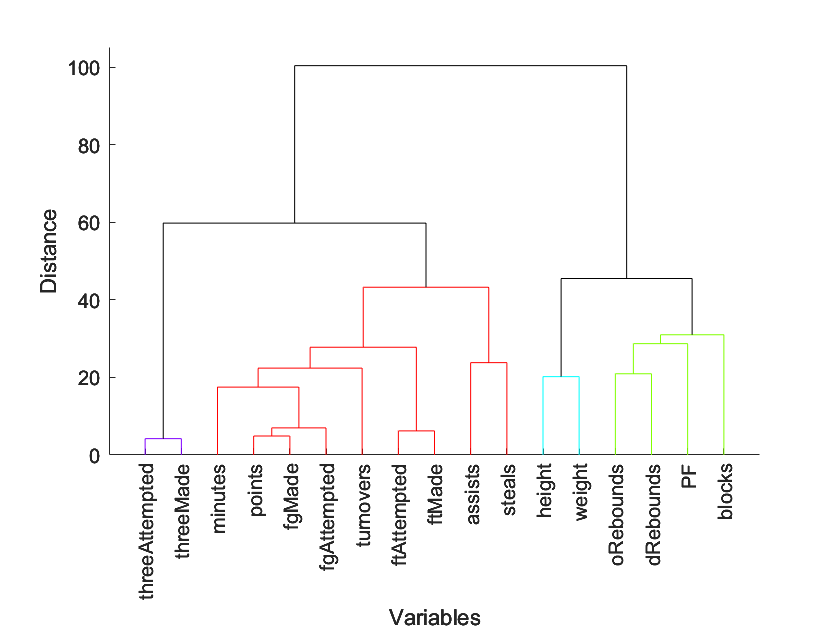

a=axes;
[~,~,outperm] = dendrogram(Z,'ColorThreshold',45);
xlabel('Variables')
ylabel('Distance')
ticklabels = labels(outperm);
a.XTickLabel = ticklabels;
a.XTickLabelRotation = 90;